# Week 3 Quiz

Use this file as a starting point for the week 3 quiz. The code to load the trained model and ground truth for the fasteners dataset is provided. You need to write code to evaluate the model and answer the questions in the Coursera quiz. Refer to the EvaluatingObjectDetectionModels.mlx file for assistance.

load fastenerTinyYolo4Detector.mat detector
load fastenerTestGT.mat fastenerTestGT

## Write code to evaluate the model

To complete this week's quiz you need to do the following steps:

- Run the detector on the test images with a confidence threshold of 0.05

- Evaluate the detection results using an IoU threshold of 0.5 and 0.25

- Compare the AP of all classes at both IoU thresholds

- Compare the mAP at both IoU thresholds

[imds, blds] = objectDetectorTrainingData(fastenerTestGT);
testData = combine(imds, blds);

## **Run the detector on the test images**

The first step to evaluate your detector is to run the detector on your test images with a small confidence threshold. In the code below, we use 0.05. This means the detector is not picky and will return many detections, even if they have low confidence. 

It took us about 10 seconds to run this on the 240 test images using a decently powered CPU. If you have a supported GPU, MATLAB will automatically use the GPU. 

Examine the output table. Notice that the detector didn't detect any objects in some images and detected multiple objects in others.

testResults = detect(detector, testData, "Threshold", 0.05)

testResults = 63×3 table
                     Boxes                        Scores            Labels      
    _______________________________________    ____________    _________________

    {[  333.6440 214.5400 57.7352 55.8290]}    {[  0.9988]}    {[Washer       ]}
    {[ 252.0627 196.8782 221.2521 88.9120]}    {[  0.0658]}    {[Washer       ]}
    {[  269.4660 174.1322 71.6475 48.3260]}    {[  0.5339]}    {[Screw        ]}
    {[  340.1252 170.1526 42.5132 87.2023]}    {[  0.9985]}    {[Screw        ]}
    {2×4 single                           }    {2×1 single}    {2×1 categorical}
    {[272.0907 114.9202 111.1460 130.4487]}    {[  0.9778]}    {[Nail         ]}
    {[ 318.1866 140.0178 71.4420 126.2814]}    {[  0.7326]}    {[Nail         ]}
    {[  328.6073 212.9534 60.7906 57.3541]}    {[  0.9287]}    {[Nut          ]}
    {[  355.6107 195.5529 59.6736 80.9760]}    {[  0.3441]}   

### Out of memory errors

When passing a `datastore` to the detect function a batch of images is pulled into memory for detection. Depending on the type of detector, image size, and your available memory, this could result in an out of memory error. If that is the case, use the `"MiniBatchSize"` Name-Value pair to reduce the number of images from the default of 128. An example is shown below.

**Important**: The detector is also run in the "Choose a detection threshold" section below. Make sure to update the call to the `detect` function to specify the `MiniBatchSize` if you are getting an out of memory error.

% testResults = detect(detector, testData, "Threshold", 0.05, "MiniBatchSize", 50)

## Visualize detections

Visualizing the detections on the images helps you evaluate the model performance. Select an image to view the detections (if any) and the associated scores. 

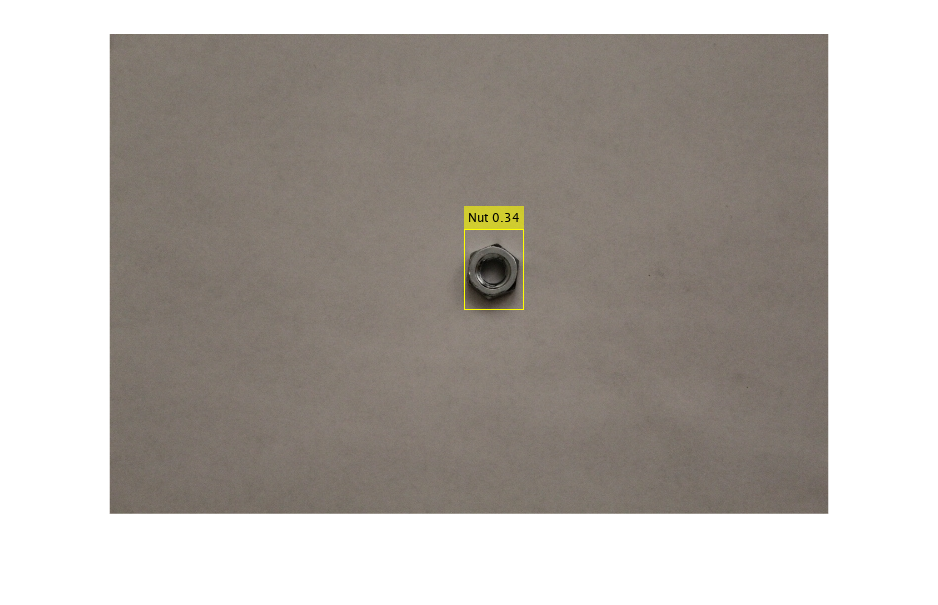

numImages = height(testResults);  % To set a limit on the control
imgIdx = 9;
img = readimage(imds, imgIdx);
label = string(testResults.Labels{imgIdx}) + " " + round(testResults.Scores{imgIdx},2);
img = insertObjectAnnotation(img, "rectangle", testResults.Boxes{imgIdx}, label);
imshow(img)

## Evaluate detection results

The `evaluateDetectionPrecision` function compares the detection results to the ground truth. The third input argument is the Intersection-over-Union (IoU) threshold used to define a true positive. The default value of 0.5 offers decent location accuracy without being too stringent and causing many false positives. However, change this value based on your application's needs. 

The function returns three outputs. The first is the average precision, AP, for each class, which tells you how well the detector performs for each class. The second and third outputs contain the recall and precision values for each class, sorted by decreasing confidence.

Run the section to evaluate the detector with the specified IoU threshold and look at the output. 

**As a bonus**, save this script with a new name, change the IoU threshold, and compare results.

% Get the list of classes from the detector
classes = detector.ClassNames;
% Evaluate the detection results
[ap, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.5);
ap

ap =     0.7065
    0.8992
    0.5315
    0.8976


The mean of the average precision across classes, or mAP, is a useful metric for evaluating the detector as a whole. 

mAP = mean(ap)

mAP = 0.7587

% Get the list of classes from the detector
classes = detector.ClassNames;
% Evaluate the detection results
[ap2, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.25);
ap2

ap2 =     0.8239
    0.9979
    0.8116
    0.9656


The mean of the average precision across classes, or mAP, is a useful metric for evaluating the detector as a whole. 

mAP2 = mean(ap2)

mAP2 = 0.8997

## Visualize precision-recall curves for different classes

Visualizing the precision-recall curves for individual classes gives you more detailed information on your detector. For example, the AP can be low due to low recall, many false positives, or both. 

Use the drop-down menu to select a class and view the precision-recall curves. Compare a few letters, like A, E, C, G, O, and Y. What do the results tell you about the performance of the detector for different classes.

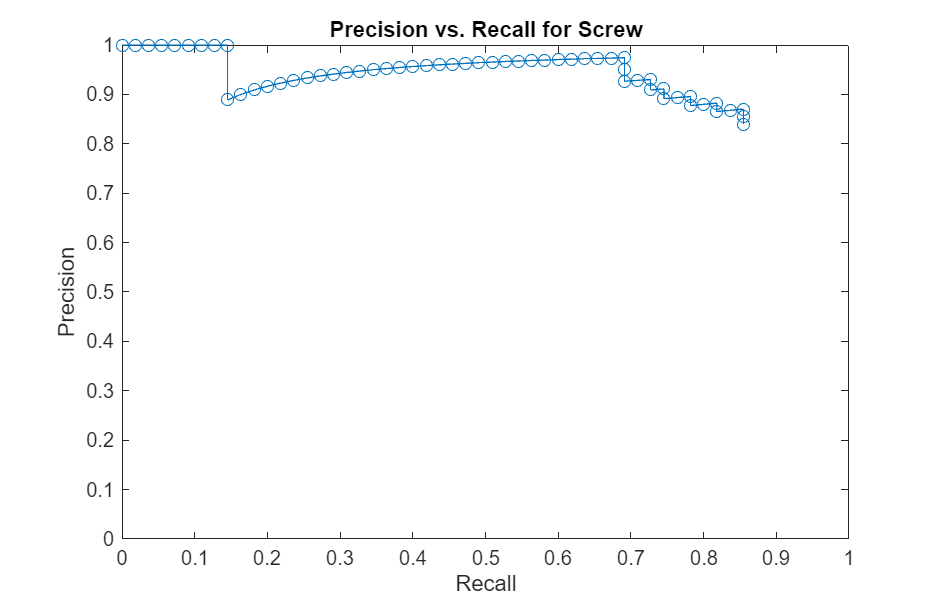

% This drop-down returns the index number for the selected class.
class = 3;
plot(recall{class}, precision{class}, "-o")
title("Precision vs. Recall for " + classes(class))
ylim([0 1])
xlim([0 1])
ylabel("Precision")
xlabel("Recall")

## Choose a detection threshold

An important parameter when detecting objects is the detection threshold value. Only detections with a confidence score greater than or equal to the threshold are returned by the detector. Increasing the threshold helps to limit false positives but can decrease recall as lower-confidence detections are removed. 

To find an appropriate threshold for your detector:

- Create a vector of threshold values to test 

- Run the detector with each threshold value

- Evaluate the detector to determine the AP for each class at each threshold

- Calculate the mAP for each threshold

- Plot the mAP vs. detection threshold

Run the code below to calculate mAP for a series of detection thresholds. 

**Note:** This may take a few minutes because the detector is being applied to every test image at multiple confidence thresholds.

% Vector of detection threshold values to test
thresholds = 0.05:0.05:0.9;

% Create a matrix to store the results
% Each column is the AP returned for the corresponding threshold value
apMatrix = zeros(length(classes), length(thresholds));

% Create a waitbar to monitor progress
f = waitbar(0);

% Loop through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(detector, testData, "Threshold", thresholds(ii));
    apMatrix(:,ii) = evaluateDetectionPrecision(results, testData, 0.5);
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

% Calculate the mAP for each threshold
% The mean function calculates the mean of each column of the matrix
mAPList = mean(apMatrix);

## Visualize mAP vs detection threshold curve

Ideally, the curve will be relatively flat as you increase the detection threshold. This means that false positives are being suppressed without decreasing recall much. However, increasing the confidence threshold too much will reduce recall, significantly lowering the mAP. In this example, choosing a detection threshold between 0.4 to 0.5 strikes a good balance. 

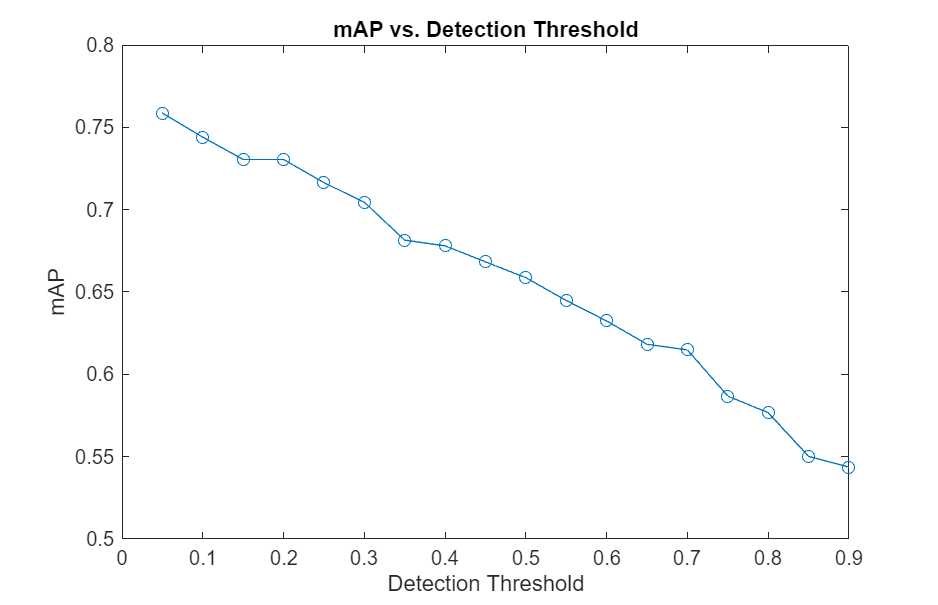

plot(thresholds, mAPList, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")

## How confident is the detector for each class?

Examine the mAP plot above.

*    A decrease in mAP as detection threshold increases means true positives are lost with the higher threshold.*

But what classes are most affected by the increased detection threshold?

Plotting a row of the `apMatrix` shows how the average precision for an individual class decreases as the detection threshold increases. 

Use the drop-down menu to look at individual classes. An AP that decreases at low detection thresholds means that there are low confidence true postitives. The detector may not be very confident for that class. The letter "E" is an example with this detector.

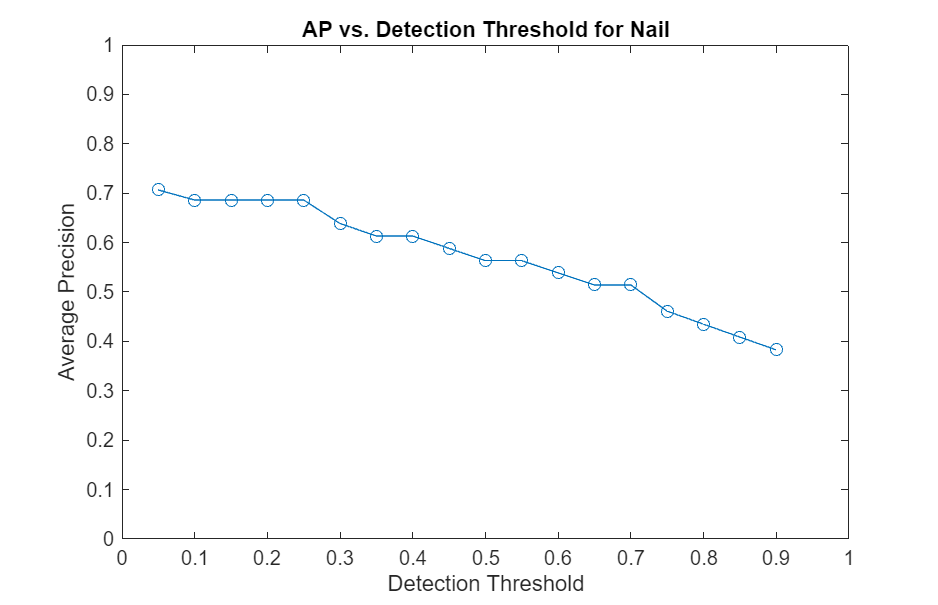

class = 1;
plot(thresholds, apMatrix(class, :), "-o")
title("AP vs. Detection Threshold for " + classes(class))
ylim([0 1])
xlim([0 1])
ylabel("Average Precision")
xlabel("Detection Threshold")

*Copyright 2024 The MathWorks, Inc.*